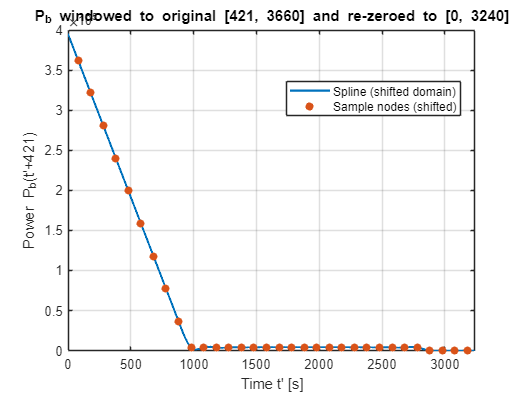

%% Plot P_b_0to3240 over [0, 3240] s (function is defined below)
t0 = linspace(0, 3240, 2001);
p0 = P_b_0to3240(t0);

figure
plot(t0, p0, 'LineWidth', 1.6); grid on
xlabel('Time t'' [s]'); ylabel('Power P_b(t''+421)');
title('P_b windowed to original [421, 3660] and re-zeroed to [0, 3240]')
xlim([0 3240])

% Overlay original 100-s sample nodes that fall inside [421, 3660], shifted to start at 0
tn_all   = 1:100:4500;
mask     = (tn_all >= 421) & (tn_all <= 3660);
tn_shift = tn_all(mask) - 421;               % now in [0, 3240]
pn_shift = P_b_0to3240(tn_shift);

hold on
scatter(tn_shift, pn_shift, 35, 'filled')
xline(0,'--'); xline(3240,'--');
legend('Spline (shifted domain)','Sample nodes (shifted)','Location','best')


%% Local functions

function power = P_b_0to3240(tprime)
% Rebase original profile window: new t' in [0, 3240] corresponds to original t = t' + 421

    % --- Power values (same as your original code) ---
    power_values = [541728.972461324, 525434.547259656, 484698.484257782, ...
                    443962.421182278, 403226.358083855, 362490.295190934, ...
                    321754.232292711, 281018.169380235, 240282.106417171, ...
                    199546.043463649, 158809.980492022, 118073.917524794, ...
                    77337.8545513178, 36601.7915815174, 4012.94120061964, ...
                    4012.94120060897, 4012.94120058611, 4012.94120055903, ...
                    4012.94120053569, 4012.94120052215, 4012.94120051169, ...
                    4012.94120050506, 4012.94120050103, 4012.94120049878, ...
                    4012.94120049977, 4012.94120050145, 4012.94120050538, ...
                    4012.94120051198, 4012.94120052045, 4012.94120053546, ...
                    4012.94120055757, 4012.94120058035, 4012.94120057094, ...
                    9.73312208790910e-10, -3.25790856001986e-10, ...
                    -7.33764827360896e-10, -3.22870604452897e-11, ...
                    -2.89901400312855e-11, -6.19593223381754e-11, ...
                    -4.77143652162351e-10, 3.07295526727322e-10, ...
                    -5.97594860992170e-10, 7.70455739254353e-10, ...
                    -4.62243586863996e-11, 65143.2880368747];

    % --- Corresponding time samples (same as your original code) ---
    time_vector = 1:100:4500;

    % Validate input in the new domain [0, 3240]
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end

    % Build spline on original samples and evaluate at shifted time t = t' + 421
    spline_fit = spline(time_vector, power_values);
    power = ppval(spline_fit, tprime + 421);
end